# Robotics II

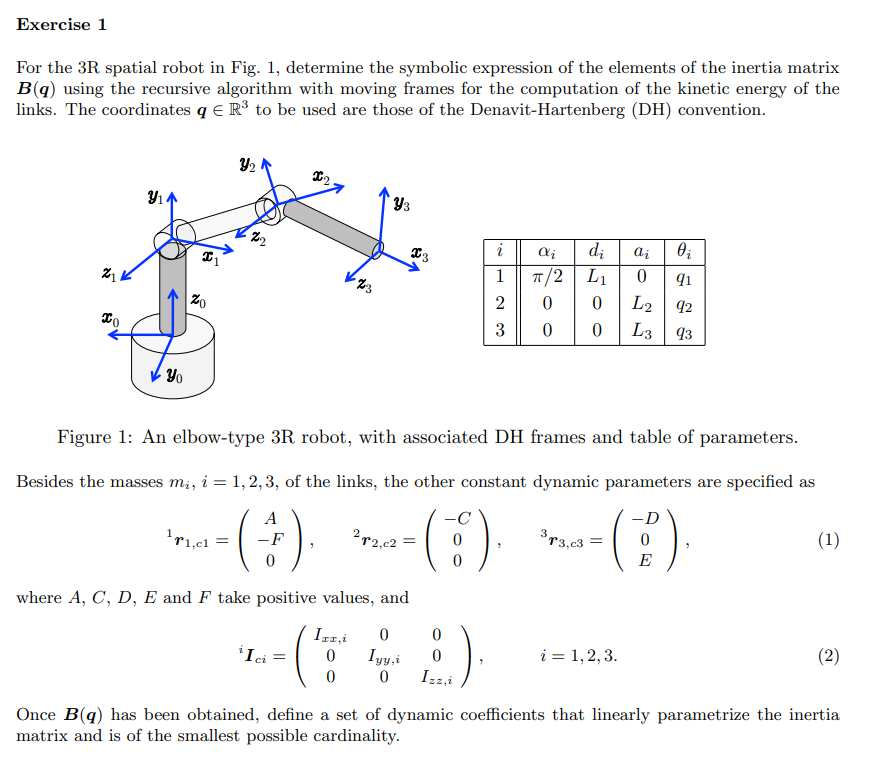

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% C=sym('C','real');
% D=sym('D','real');
% F=sym('F','real');
% E=sym('E','real');
% 
% A=sym('A','real');
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% isMotor=0;

% % % %Insert manually the global positions of the centers of mass
% % % pc(:,1) = [q(1) 0];
% % % pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% % % pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% % % [pct,qt]=ToTimedep(pc,n,'t','q')
% % % vct = diff(pct,t)
% % % [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% % % w =[0, qd(2), qd(2)].';
% % % % for i=1:n
% % % %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % % % end
% % % % KE = sum(T.')
% % % % 
% % % 

%  %       alpha   a   d   theta
% dhTable = [pi/2  0      l(1)    q(1);
%            0    l(2)    0       q(2);
%            0    l(3)    0       q(3)]
% 
% R2Robot=['rrr';'zxx';[1,1,1]]       

% rc=[A,-C,-D;-F,0,0;0,0,E]
% methodD=2;
% movingframes=true
% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,[],methodD,dhTable,'alpha',rc,movingframes)

## optimal sort

% 
% optiomalSortD(Ti' ,[m',qd' ])

## minimal parametrization

%  [C,cac,Csubs,S] = getCs(M,q,qd);
%  [Msubs, dynamicParameters, a] = getDynamicParameters(M,q,[l'],2)%l')
%  [Csubs,cacsubs,Csubssubs,Ssubs] = getCs(Msubs,q,qd)
%  
%  

## exercise 3

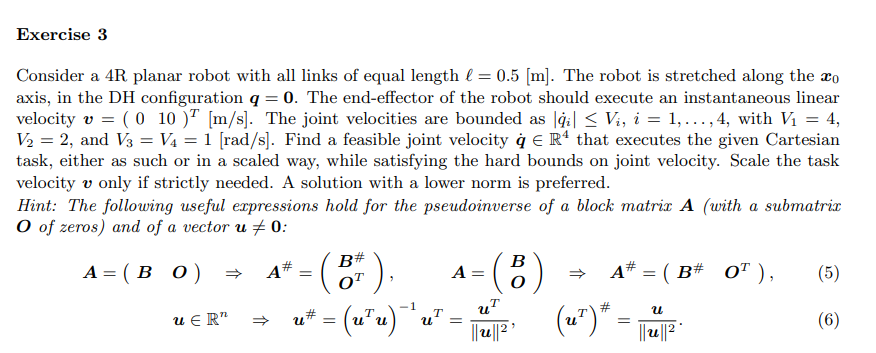

clear; clc;
q_dMax_ = [4,2,1,1] % Maximum acceleration constraints of joints

q_dMax_ =      4     2     1     1



q_dMaxTemp_ = q_dMax_ % Maximum acceleration constraints of joints

q_dMaxTemp_ =      4     2     1     1


V_=[0,10]'

V_ =      0
    10


qnum = 4; %Number of joints
q = sym('q', [1 qnum],'real');
d = sym('d', [1 qnum],'real');
a = sym('a', [1 qnum],'real');

L = sym('l','real')

$$L = l$$

L_=0.5

L_ = 0.5000

% a, alpha, 
R3Robot = [L 0 0 q(1);
           L 0 0 q(2);
           L 0 0 q(3);
           L 0 0 q(4)]

$$R3Robot = \left(\begin{array}{cccc} l & 0 & 0 & q_{1}\\ l & 0 & 0 & q_{2}\\ l & 0 & 0 & q_{3}\\ l & 0 & 0 & q_{4} \end{array}\right)$$

       
T0_EE = getTransformationMatrix(R3Robot)

$$T0\_EE = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l\,\left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ \sigma_{1} & \sigma_{2} & 0 & l\,\left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}$$


% Calculate the Jacobian (Rotational)
config = 'RRRR';
[Jp, Jo,Jps, Jos] = getJacobian(R3Robot,config)

$$Jp = \begin{array}{l} \left(\begin{array}{cccc} -l\,\left(\sigma_{3}+\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -l\,\left(\sigma_{3}+\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -l\,\left(\sigma_{3}+\sigma_{1}\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{4}+\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & l\,\left(\sigma_{4}+\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & l\,\left(\sigma_{4}+\sigma_{2}\right) & l\,\sigma_{2}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$Jo = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

$$Jps = \left(\begin{array}{cccc} -l\,\left(s_{1}+s_{1,2}+s_{1,2,3}+s_{1,2,3,4}\right) & -l\,\left(s_{1,2}+s_{1,2,3}+s_{1,2,3,4}\right) & -l\,\left(s_{1,2,3}+s_{1,2,3,4}\right) & -l\,s_{1,2,3,4}\\ l\,\left(c_{1}+c_{1,2}+c_{1,2,3}+c_{1,2,3,4}\right) & l\,\left(c_{1,2}+c_{1,2,3}+c_{1,2,3,4}\right) & l\,\left(c_{1,2,3}+c_{1,2,3,4}\right) & c_{1,2,3,4}\,l\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$Jos = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

%Jac = [Jp;Jo]
%Eliminate the zero rows, which represent the unused variables
Jp = Jp(~all(Jp == 0,2),:)

$$Jp = \begin{array}{l} \left(\begin{array}{cccc} -l\,\left(\sigma_{3}+\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -l\,\left(\sigma_{3}+\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -l\,\left(\sigma_{3}+\sigma_{1}\right) & -l\,\sigma_{1}\\ l\,\left(\sigma_{4}+\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & l\,\left(\sigma_{4}+\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & l\,\left(\sigma_{4}+\sigma_{2}\right) & l\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


q_ = [0, 0, 0,0]

q_ =      0     0     0     0


J_ = subs(Jp, [q L], [q_ L_])

$$J\_ = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 2 & \frac{3}{2} & 1 & \frac{1}{2} \end{array}\right)$$

digits(5)
vpa(J_)

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 2.0 & 1.5 & 1.0 & 0.5 \end{array}\right)$$

rank_J_=rank(J_)

rank_J_ = 1

rank_V_=rank(V_)

rank_V_ = 1

if(rank_J_<2)
disp("Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!")
if(rank_J_==rank_V_)
disp("but The rank is inside of rank V_ all are: "+rank_J_)
disp("BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!")
end
end

Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!


but The rank is inside of rank V_ all are: 1


BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!


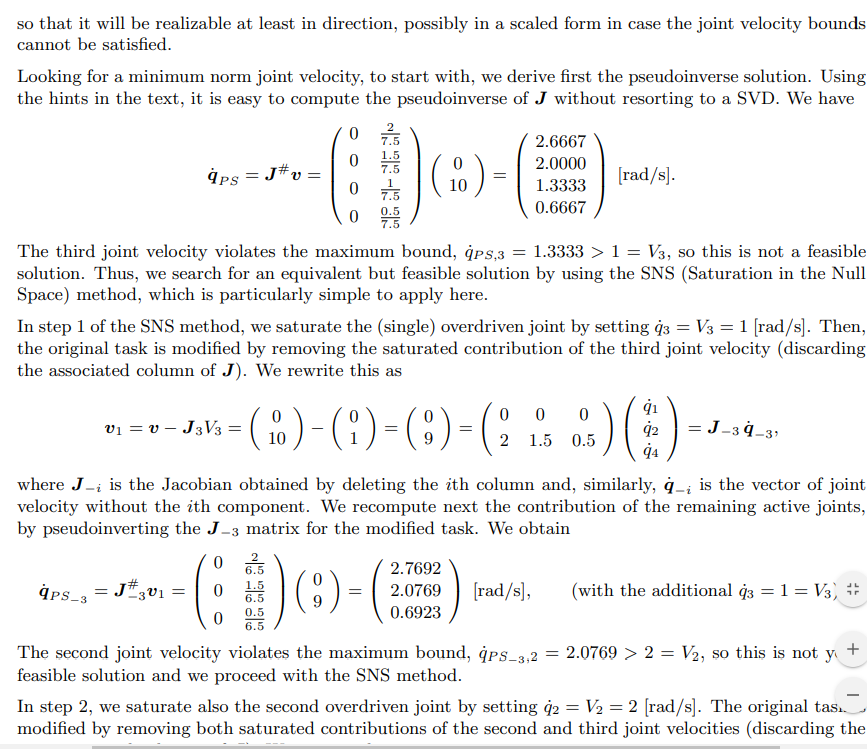

V_=[0,10]'

V_ =      0
    10


abs_on=false;
 [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on)

qdotPS =     2.6667
    2.0000
    1.3333
    0.6667


qdotstar =     2.6667
    2.0000
    1.3333
    0.6667


Max value that violates is:  3  with value:  0.33333
SNS Iterarion:  1
Jtemp #:  3


$$Jtemp = \left(\begin{array}{ccc} 0 & 0 & 0\\ 2 & \frac{3}{2} & \frac{1}{2} \end{array}\right)$$

Jtemp pseudo inverse #:  3


$$psJ\_ = \left(\begin{array}{cc} 0 & 0.30769\\ 0 & 0.23077\\ 0 & 0.076923 \end{array}\right)$$

qdot_components =     2.7692    2.0769    0.6923


qdot_sns =     2.7692
    2.0769
    0.6923


Max value that violates is:  2  with value:  0.0769
SNS Iterarion:  1
Jtemp #:  2


$$Jtemp = \left(\begin{array}{cc} 0 & 0\\ 2 & \frac{1}{2} \end{array}\right)$$

Jtemp pseudo inverse #:  2


$$psJ\_ = \left(\begin{array}{cc} 0 & 0.47059\\ 0 & 0.11765 \end{array}\right)$$

qdot_components =     2.8235    0.7059


qdot_sns =     2.8235
    0.7059


[INFO] No values are exceeding the limits.
Result:


qdotstarFinal =     2.8235
    2.0000
    1.0000
    0.7059


qdotstarFinal =     2.8235
    2.0000
    1.0000
    0.7059



[qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)

Assuming qN positive if it is not in this way comment this line  PAY ATTENTION!


n = 4

Result:


$$qdotstar = \left(\begin{array}{c} \frac{10}{3}\\ \frac{3}{2}\\ \frac{2}{3}\\ \frac{5}{6} \end{array}\right)$$

$$qdotstarFinal = \left(\begin{array}{c} \frac{10}{3}\\ \frac{3}{2}\\ \frac{2}{3}\\ \frac{5}{6} \end{array}\right)$$

W =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



vpa(qdotstarFinal)

$$ans = \left(\begin{array}{c} 3.3333\\ 1.5\\ 0.66667\\ 0.83333 \end{array}\right)$$

pd2_=vpa(J_)*qdotstarFinal

$$pd2\_ = \left(\begin{array}{c} 0\\ 10.0 \end{array}\right)$$

vpa(norm(qdotstarFinal))

$$ans = 3.8079$$

## exercise 4

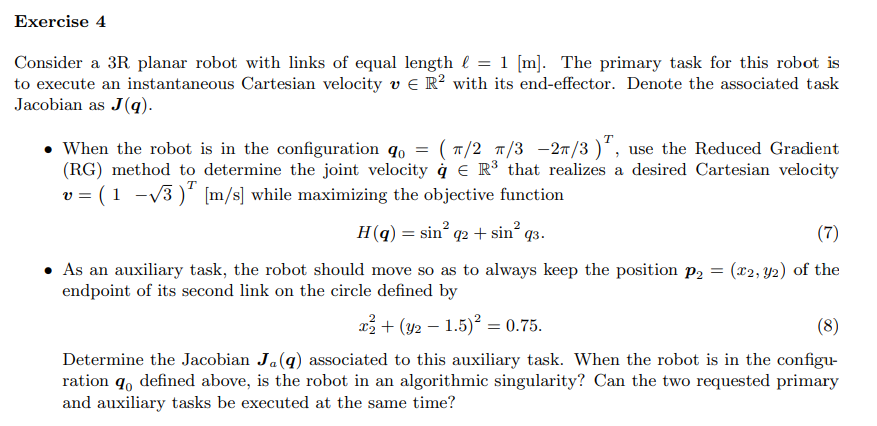

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% 
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% 

% % %Insert manually the global positions of the centers of mass
% % pc(:,1) = [q(1) 0];
% % pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% % pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% % [pct,qt]=ToTimedep(pc,n,'t','q')
% % vct = diff(pct,t)
% % [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% % w =[0, qd(2), qd(2)].';
% % % for i=1:n
% % %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % % end
% % % KE = sum(T.')
% % % 
% % 

% % 
% % % R2Robot = [0 l(1) 0 q(1);
% % %            0 l(2) 0 q(2)]
% % 
% % DHtable = [ 0    0       q(1)    0;
% %             0    l(2)    0       q(2);
% %             0    l(3)    0       q(3)
% %             ]
% % % [Jp, Jo,Jps, Jos] = getJacobian(DHtable,[1,0,0],'alpha')
% R2Robot=['rrr';'xxx';[1,1,1]]       
% % % R2Robot=['rr';'x~']       

% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)

% %  [C,cac,Csubs,S] = getCs(M,q,qd)
% %  [Msubs, dynamicParameters, a] = getDynamicParameters(M,q,[])%l')
% % [Csubs,cacsubs,Csubssubs,Ssubs] = getCs(Msubs,q,qd)
% H=sin(q(2))^2+sin(q(3))^2;
% V_=[1,-sqrt(3)]'
% q_=[pi/2,pi/3,-2*pi/3]'
% dir=1%%maximizing
% l_=[1,1,1]'
% J_=subs(J,l,l_)
% [qd,qd_,vH,vH_,gh,gh_] = ProjectedGradient(q,dir,J_,V_,H,[],q_);
% vpa(qd_)
% vpa(gh_)
% vH_
% [qd,qd_,vH2,vH2_,gh2,gh2_] = ProjectedGradient(q,-1,J_,V_,H,[],q_);
% vpa(qd_)
% vpa(gh2_)
% vH2_
% 

## task augmentation

% nDOF=2
% pred=PCVar.PTotali(:,nDOF)
% varstoreplace=[q',l']
% varstoreplace_=[q_',l_']
% x=sym('x','real');
% y=sym('y','real');
% fpath=x^2+(y^2-1.5)^2-0.75
% [Je,Ve,Ja,Je_,Ve_,Ja_]=TaskAugmentation(pred,nDOF,J,fpath,[x,y]',q,qd,varstoreplace,varstoreplace_);
% 
% 
% 
% q_plus=inv(Je_)*[V_',0]'


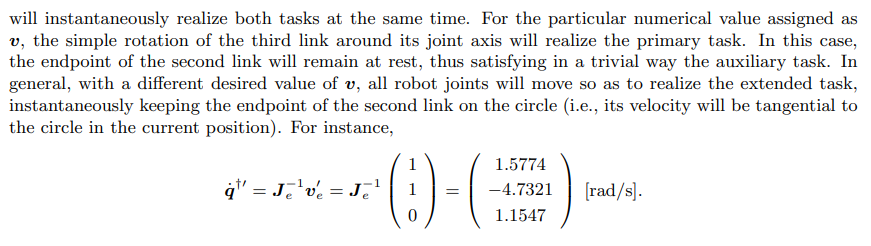

## Exercsie 5

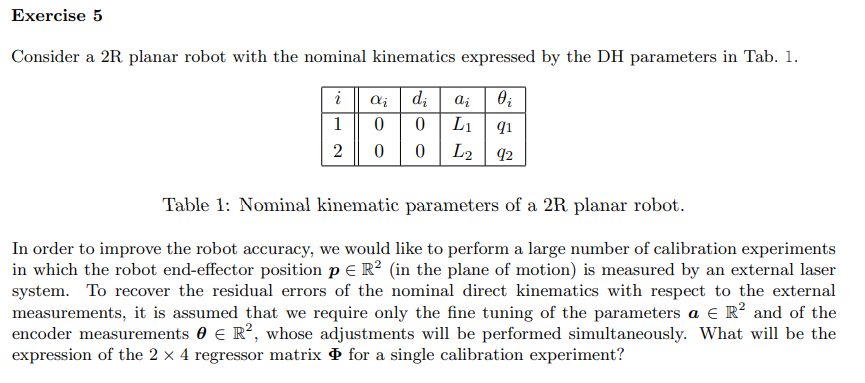

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% C=sym('C','real');
% D=sym('D','real');
% F=sym('F','real');
% E=sym('E','real');
% 
% A=sym('A','real');
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% isMotor=0;
% 

%  %       alpha   a   d   theta
% dhTable = [0  l(1)  0  q(1);
%            0  l(2)  0  q(2);
%            0  l(3)  0  q(3)]
% 
% R2Robot=['rrr';'xxx';[1,1,1]]       

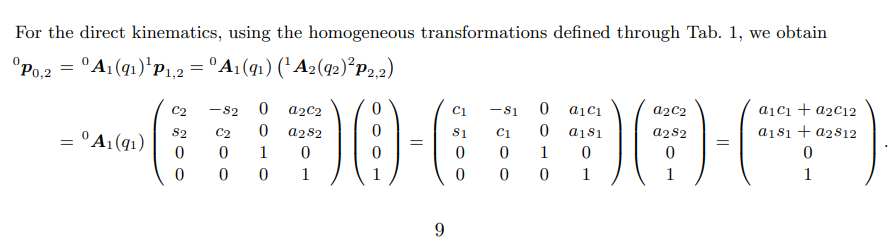

% % rc=[A,-C,-D;-F,0,0;0,0,E]
% methodD=2;
% movingframes=false
% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I,methodD,dhTable,'alpha',[],movingframes)
% PC1=Pc%(1:end-1,end)
% 

## dynamics parameters and jacobians

% 
% %  [C,cac,Csubs,S] = getCs(M,q,qd);
%  [psubs, dynamicParameters, aP] = getDynamicParameters(PC1(:,end),q,[],1)%l')
% %  [Csubs,cacsubs,Csubssubs,Ssubs] = getCs(Msubs,q,qd)

## jacobians

% 
% Ja=jacobian(psubs(:,end),aP)
% syms J_theta
% J_theta=jacobian(psubs(:,end),q)
% 

## regresor

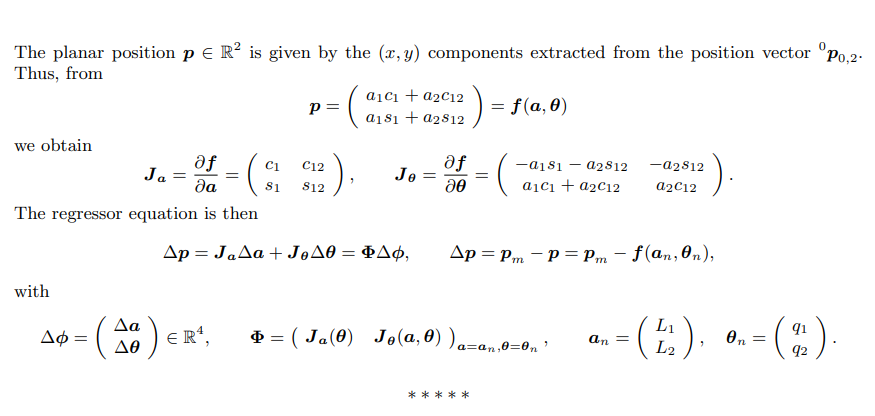

% disp("no lo terminé de poner en simbolico, no tiene sentido ahah")
% % % % % syms delta_p real
% % % % a_n=sym('a_n','real')
% % % % theta_n=sym('theta_n','real')
% % % % syms f(a_n,theta_n) 
% % % % f
% % % % % syms delta_psi real
% % % % delta_p=sym('Delta_p','real')
% % % % p=sym('p','real')
% % % % p_m=sym('p_m','real')
% % % % 
% % % % delta_theta=sym('Delta_theta','real')
% % % % delta_a=sym('Delta_a','real')
% % % % phi=sym('phi','real')
% % % % Phi=sym('Phi','real')
% % % % 
% % % % delta_phi=[delta_a;delta_theta] 
% % % % % disp("son lo mismo no confundir")
% % % % delta_P_=delta_p == Ja*delta_a + Jtheta*delta_theta
% % % % % delta_p_=p_m-p
% % % % % delta_p__=p_m-







